# CS283 Assignment 2

Enmao Diao, 2017/09/22

*Note: Matlab requires that all local functions in a live script appear at the end of the script. So, your code defining functions getT(), getH(), applyH(), applyH2(), and ransacH() must appear at the very bottom of this file, after all other code that makes references to those functions. Also, each function definition must terminate with "end". More information is in the *[Matlab documentation](https://www.mathworks.com/help/matlab/matlab_prog/local-functions-in-scripts.html)*.*

# Question 1

## 1 (a)

From similarity transformation, we have, $x_i^\prime = \frac{sx_i+t_x}{t_x+t_y+1}$, $y_i^\prime = \frac{sy_i+t_y}{t_x+t_y+1}$            (1)

for centroid = $(0,0)$, we have $\frac{1}{N}\sum_{i} x_i^\prime = 0$, and $\frac{1}{N}\sum_{i} y_i^\prime= 0$            (2)

for the average distance from the origin  is $\sqrt2$, we have $\frac{1}{N}\sum_i\sqrt{(x_i^\prime)^2+(y_i^\prime)^2} = \sqrt2$            (3)

from (1) and (2) we have $\sum_{i} x_i = -\frac{Nt_x}{s}$,$\sum_{i} y_i = -\frac{Nt_y}{s}$,$t_y =\frac{t_x\sum_{i} y_i}{\sum_{i} x_i}$            (4)

from (1), (3) and (4) we have 


$$\frac{1}{N}\sum_i\sqrt{(\frac{sx_i+t_x}{t_x+t_y+1})^2+(\frac{sy_i+t_y}{t_x+t_y+1})^2} = \sqrt2$$



$$\frac{1}{N}\sum_i\sqrt{(sx_i+t_x)^2+(sy_i+t_y)^2} = (t_x+t_y+1)\sqrt2$$



$$\sum_i\sqrt{(-\frac{Nt_xx_i}{\sum_{i} x_i}+t_x)^2+(-\frac{Nt_yy_i}{\sum_{i} y_i}+t_y)^2} =N(t_x+t_y+1)\sqrt2$$



$$\sum_i\sqrt{t_x^2[(1-\frac{Nx_i}{\sum_i x_i})^2+(\frac{\sum_i y_i}{\sum_I x_i})^2(1-\frac{Ny_i}{\sum_i y_i})^2]} =N\sqrt2(\frac{t_x(\sum_i x_i+\sum_{i} y_i)}{\sum_{i} x_i}+1)$$



$$t_x\sum_i\sqrt{[(1-\frac{Nx_i}{\sum_i x_i})^2+(\frac{\sum_i y_i}{\sum_I x_i})^2(1-\frac{Ny_i}{\sum_i y_i})^2]} -N\sqrt2(\frac{t_x(\sum_i x_i+\sum_{i} y_i)}{\sum_{i} x_i})=N\sqrt2$$



$$t_x =\frac{N\sqrt2}{\sum_i\sqrt{[(1-\frac{Nx_i}{\sum_i x_i})^2+(\frac{\sum_i y_i}{\sum_I x_i})^2(1-\frac{Ny_i}{\sum_i y_i})^2]}-N\sqrt2(\frac{\sum_i x_i+\sum_{i} y_i}{\sum_{i} x_i})}$$
            

follow this result and (4) and can have expression for $s,t_x,t_y$

## 1(b) 

see function getT() below

## 1(c) 

In line 3, we first transpose X from 50x2 to 2x50 and append a zero vector 1x50 vertically. In this way, we construct a matrix exactly from $\left(xi,yi\right)$ to $\left(xi,yi,1{\left.\right)}^T \right.$. Following the formula shown in th pset, we can then do matrix muliplication T*X to get X'. Note that, the final coordinate of this result is not necessarily equal to one.

In line 4, we normalize the result from line 3 $\left(a,b,c{\left.\right)}^T \right.$ to  ${\left(\frac{a}{c},\frac{b}{c},1\right)}^T$ which is the is the representation of point ${\left(\frac{a}{c},\frac{b}{c}\right)}^T$ in R2 by adding a final coordinate of 1.  

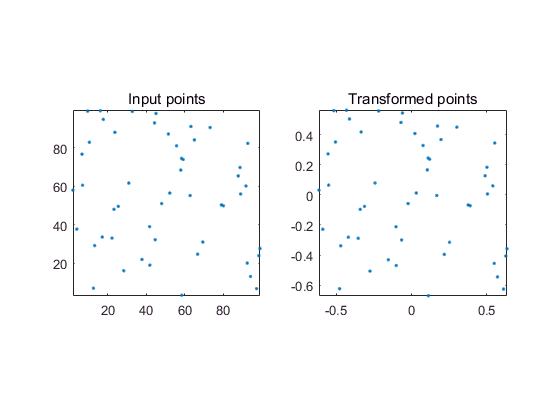

X = rand(50,2)*100;    % 50 random points in square [0,100]x[0,100]
T = getT(X);            
Xn = (T*[X'; ones(1,50)])';
Xni = Xn(:,1:2)./repmat(Xn(:,3),[1 2]);

% display results
figure;
subplot(1,2,1); plot(X(:,1),X(:,2),'.'); 
axis equal; axis tight; title 'Input points';
subplot(1,2,2); plot(Xni(:,1),Xni(:,2),'.'); 
axis equal; axis tight; title 'Transformed points';

# Question 2

## 2 (a)

see function getH() below

## 2 (b)

see function applyH() below

## **2 (c)**

 We manually denoted 4 points for this image because H has 8 degress of freedom. 4 points give us enough constraints. Then we follow normalized DLT algorithm and get H. We apply H by following the hint. We first transform 4 corners and retrieve the limit of transformed image. Then we use meshgrid to get the combination of indices. Next we apply $H^{−1}$ for those coordinates to get their image in the original picture. Finally we can interpolate through through the image with the exact coordinates from the original picture.

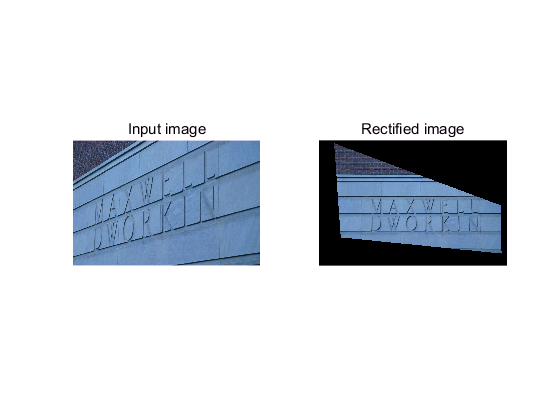

% read image, convert to grayscale with single precision 
%  (doing it in color requires a little extra work; try it only after you get the grayscale version working) 
% im=single(rgb2gray(imread(fullfile('.','data','MaxwellDworkin_01.jpg'))));
im=imread(fullfile('.','data','MaxwellDworkin_01.jpg'));
% figure;
% imshow(im,[]);
% impixelinfo;
X1 = [255,267;250,443;548,96;543,298];
X2 = [0,0;0,1;2.5,0;2.5,1];
H = getH(X1,X2);
% replace the next line with your own code
imout = applyH(im, H);


% display results
figure;
subplot(1,2,1); imshow(im,[]); title 'Input image';
subplot(1,2,2); imshow(imout,[]); title 'Rectified image';

# Question 3

## 3(a)

See function applyH2() below.

## 3(b)

We first use similar method in P2 to retrieve the tranformed image of quad_left and quad_right. Then we try to combine three images as much as possible. We let the limit to be the upper and lower bound of three images. The trick we use is that we set the quad_left as the origin instead of quad_middle. We can directly initialize the final matrix and fill in with those three separate images. The difficulty is to construct proper logical mapping such that they combine as much as possible.

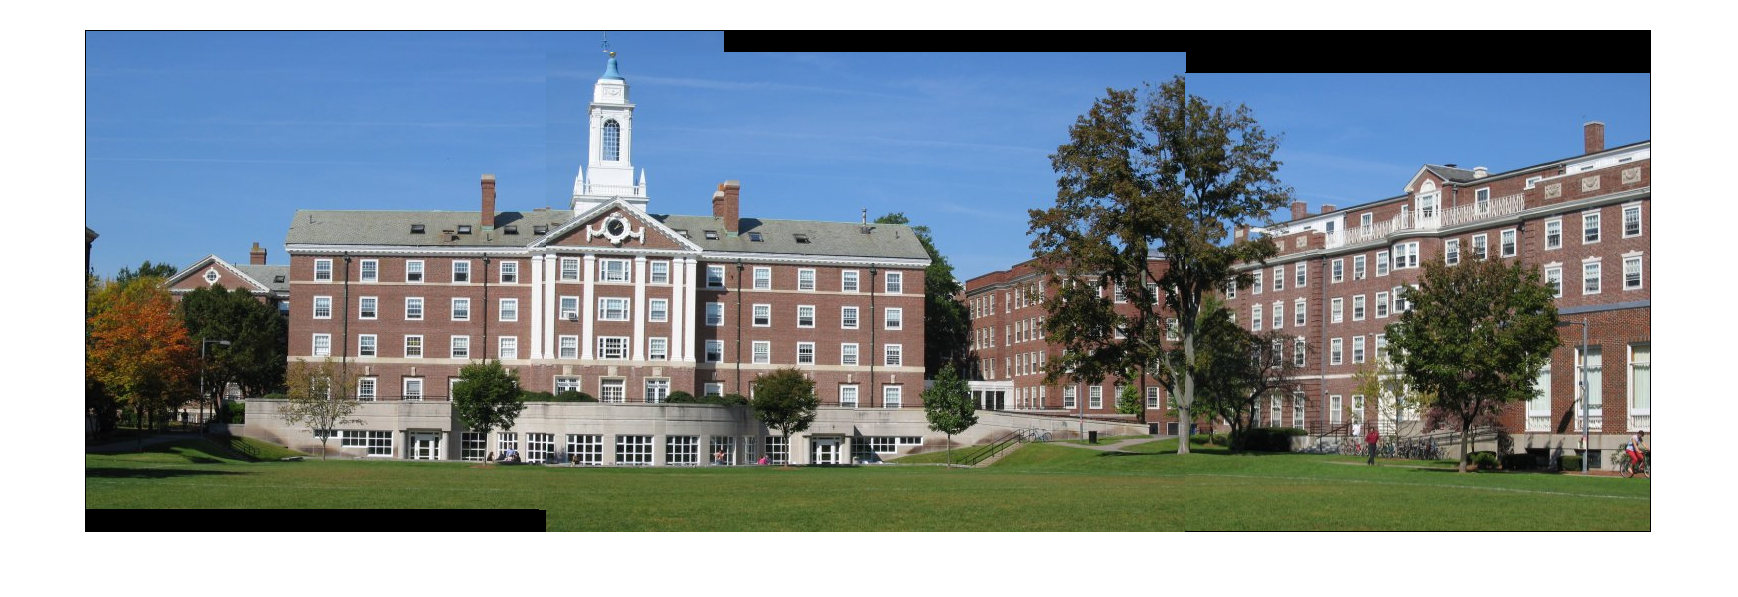

% read images, convert to grayscale with single precision 
%  (doing it in color requires a little extra work; try it only after you get the grayscale version working) 
% im1=single(rgb2gray(imread(fullfile('.','data','quad_left.jpg'))));
% im2=single(rgb2gray(imread(fullfile('.','data','quad_middle.jpg'))));
% im3=single(rgb2gray(imread(fullfile('.','data','quad_right.jpg'))));
im1=single(imread(fullfile('.','data','quad_left.jpg')));
im2=single(imread(fullfile('.','data','quad_middle.jpg')));
im3=single(imread(fullfile('.','data','quad_right.jpg')));
% figure;
% imshow(im2,[]);
% impixelinfo;

% here, type in the coordinates of your manually-identified pixels, using the following variables:
%  X12: Nx2 array of points in quad_left that match points in quad_middle
%  X21: Nx2 array of points in quad_middle that match points in quad_left
%  X23: Mx2 array of points in quad_middle that match points in quad_right
%  X32: Mx2 array of points in quad_right that match points in quad_middle
X12 = [514,268;514,291;545,268;545,291];
X21 = [53,246;53,269;84,246;84,269];
X23 = [545,335;544,357;556,335;556,357];
X32 = [81,329;80,352;92,329;92,352];

% compute and display the panoramic result
figure;
imout = applyH2(im1,im2,im3,getH(X12,X21),getH(X32,X23));
imshow(imout,[]);

# Question 4

## 4(a)

See function ransacH() below.

## 4(b)

We first use RANSAC to robustly optimize $H$and then use similar methods from P3 to combine these three images. However, the result is somewhat similar or even worse than my own manual implementation. The benefit, however, is that this framework is almost automatic and therefore we can apply this method for many images efficiently.

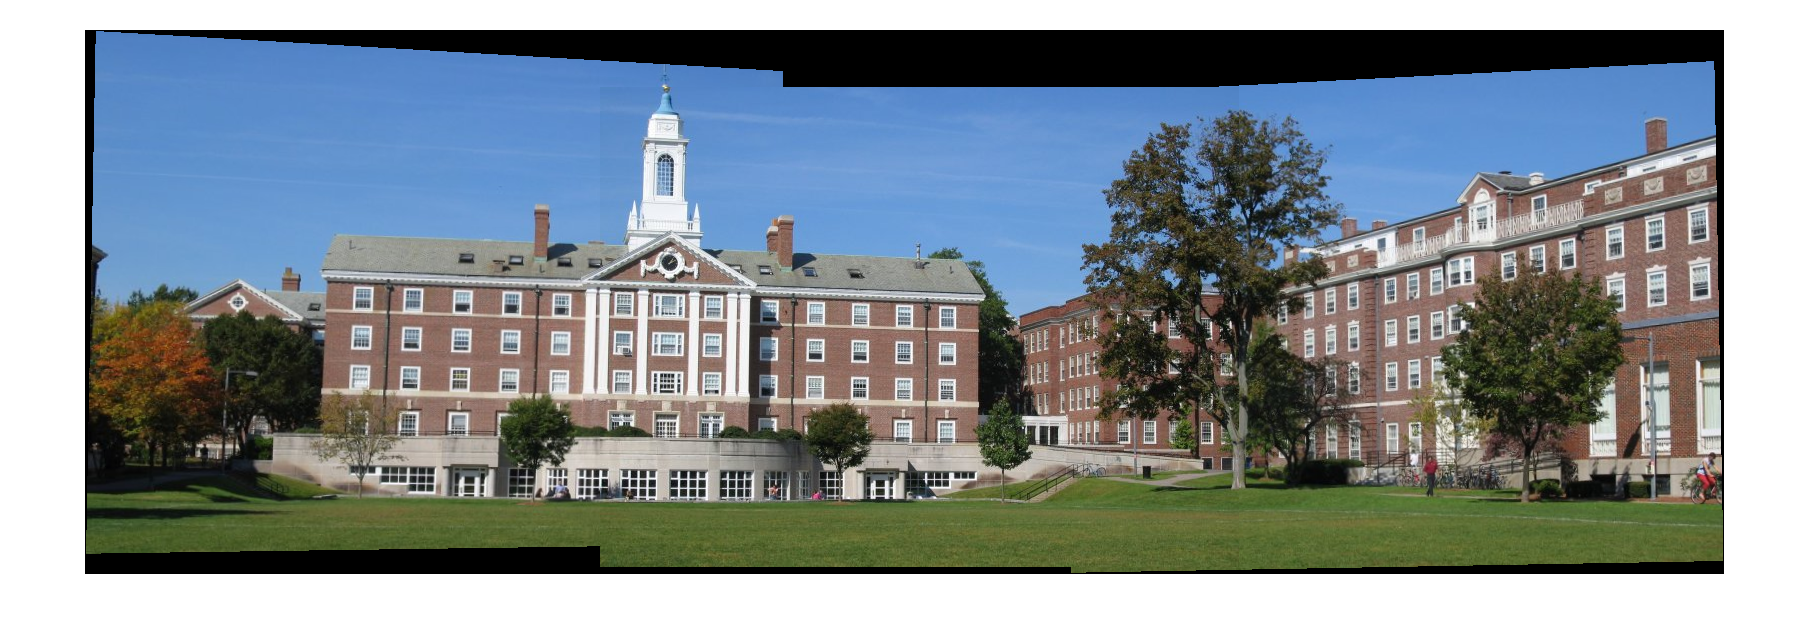

% read images, convert to grayscale with single precision 
%  (doing it in color requires a little extra work; try it only after you get the grayscale version working) 
im1=imread(fullfile('.','data','quad_left.jpg'));
im2=imread(fullfile('.','data','quad_middle.jpg'));
im3=imread(fullfile('.','data','quad_right.jpg'));

% load (noisy) correspondences. These are the variables:
%  X12: points in quad_left that match points in quad_middle
%  X21: points in quad_middle that match points in quad_left
%  X23: points in quad_middle that match points in quad_right
%  X32: points in quad_right that match points in quad_middle
load(fullfile('.','data','quad_points.mat'));

% compute and display the panoramic result
%figure;
imout = applyH2(im1,im2,im3,ransacH(X12,X21),ransacH(X32,X23));
imshow(imout,[]);

# Local functions

function T = getT(X)
% Question 1(b)
% Similarity matrix T that normalizes a set of 2D points. Input
% X is an Nx2 array of inhomgeneous image coordinates. Output is
% an invertible 3x3 matrix.

% check input
if ((~ismatrix(X)) || (size(X, 2) ~= 2) || (size(X, 1) == 0))
	error('Input must be an Nx2 array.');
end
N = size(X,1);
x = X(:,1);
y = X(:,2);
sum_X = sum(X,1);
sum_x = sum_X(1);
sum_y = sum_X(2);
part1 = sum(sqrt((1-N*x/sum_x).^2 + (sum_y/sum_x)^2*(1-N*y/sum_y).^2));
part2 = N*sqrt(2)*(sum_x+sum_y)/sum_x;
tx = N*sqrt(2)/(part1 -part2);
ty = tx*sum_y/sum_x;
s = -N*tx/sum_x;

% replace the next line with your own code
T = [s,0,tx;0,s,ty;0,0,1];

end % end function getT

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function H = getH(X1, X2)
% Question 2(a)
% Homography that maps points in X1 to points in X2. Inputs
% X1, X2 are Nx2 arrays of inhomgeneous image coordinates. Output is
% an invertible 3x3 matrix. Requires function getT().

% check input
if ((~ismatrix(X1)) || (~ismatrix(X2)) || ~isempty(find(size(X1) ~= size(X2), 1))...
		|| (size(X1, 2) ~= 2) || (size(X1, 1) == 0))
	error('Input must be two Nx2 matrices.');
end
N = size(X1,1);
T1 = getT(X1);
T2 = getT(X2);
X1n = (T1*[X1'; ones(1,N)])';
X2n = (T2*[X2'; ones(1,N)])';
wixi = repmat(X2n(:,3),1,3).* X1n;
yixi = repmat(X2n(:,2),1,3).* X1n;
xixi = repmat(X2n(:,1),1,3).* X1n;
A = [zeros(N,3),-wixi,yixi;wixi,zeros(N,3),-xixi];
[U,D,V] = svd(A);
V_last = V(:,end);
H_tilde = [V_last(1:3)';V_last(4:6)';V_last(7:9)'];
% replace the next line with your own code
H = inv(T2)*H_tilde*T1;
end % end function getH

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function Iout = applyH(Iin, H)
% Question 2(b)
% Warp image Iin using homography H. Inputs are image Iin
% and 3x3 invertible matrix H. Output is image Iout, possibly of different
% height and width than input.
[m,n,c] = size(Iin);
corners = [1,1,1;1,m,1;n,1,1;n,m,1]';
limits = H*corners;
limits = limits./repmat(limits(3,:),3,1);
xmin = floor(min(limits(1,:)));xmax = ceil(max(limits(1,:)));
ymin = floor(min(limits(2,:)));ymax = ceil(max(limits(2,:)));
num_x_pts = n;
num_y_pts = m;
% create regularly-spaced grid of (x,y)-pixel coordinates
[x,y]=meshgrid(linspace(xmin,xmax,num_x_pts), linspace(ymin,ymax,num_y_pts));
% reshape them so that a homography can be applied to all points in parallel
X=[x(:) y(:)];
% [Apply a homography to homogeneous coordinates corresponding to ‘X’. ] %
x_prime = [X';ones(1,num_x_pts*num_y_pts)];
x_org = inv(H)*x_prime;
% [Compute inhomogeneous coordinates of mapped points. ] %
% [Save result in Nx2 matrix named ‘Xh’. ] %
Xh = (x_org./repmat(x_org(3,:),3,1))';
Iout = zeros(num_y_pts,num_x_pts,c);
for i=1:c
% interpolate I to get intensity values at image points ‘Xh’
Ih=interp2(double(Iin(:,:,i)),Xh(:,1),Xh(:,2),'linear');
% reshape intensity vector into image with correct height and width
Ih=reshape(Ih,[num_y_pts,num_x_pts]);
% Points in ‘Xh’ that are outside the boundaries of the image are assigned
% value ‘NaN’, which means ‘not a number’. The final step is to
% set the intensities at these points to zero.
Ih(isnan(Ih))=0;
Iout(:,:,i) = Ih;
end
Iout = uint8(Iout);
end % end function applyH
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function Iout = applyH2(I1,I2,I3,H12,H32)
% Question 3(a)
% Create a panoramic image from images I1, I2, and I3 using 3x3 invertible matrices H12 and H32.
[m1,n1,c1] = size(I1);
corners = [1,1,1;1,m1,1;n1,1,1;n1,m1,1]';
limits = H12*corners;
limits = limits./repmat(limits(3,:),3,1);
xmin_1 = floor(min(limits(1,:)));xmax_1 = ceil(max(limits(1,:)));
ymin_1 = floor(min(limits(2,:)));ymax_1 = ceil(max(limits(2,:)));
num_x_pts_1 = xmax_1-xmin_1+1;
num_y_pts_1 = ymax_1-ymin_1+1;
% create regularly-spaced grid of (x,y)-pixel coordinates
[x,y]=meshgrid(linspace(xmin_1,xmax_1,num_x_pts_1), linspace(ymin_1,ymax_1,num_y_pts_1));
% reshape them so that a homography can be applied to all points in parallel
X=[x(:) y(:)];
% [Apply a homography to homogeneous coordinates corresponding to ‘X’. ] %
x1_prime = [X';ones(1,num_x_pts_1*num_y_pts_1)];
x12 = inv(H12)*x1_prime;
% [Compute inhomogeneous coordinates of mapped points. ] %
% [Save result in Nx2 matrix named ‘Xh’. ] %
Xh = (x12./repmat(x12(3,:),3,1))';
Iout12 = zeros(num_y_pts_1,num_x_pts_1,c1);
for i=1:c1
% interpolate I to get intensity values at image points ‘Xh’
Ih=interp2(double(I1(:,:,i)),Xh(:,1),Xh(:,2),'linear');
% reshape intensity vector into image with correct height and width
Ih=reshape(Ih,[num_y_pts_1,num_x_pts_1]);
% Points in ‘Xh’ that are outside the boundaries of the image are assigned
% value ‘NaN’, which means ‘not a number’. The final step is to
% set the intensities at these points to zero.
Ih(isnan(Ih))=0;
Iout12(:,:,i) = Ih;
end


[m3,n3,c3] = size(I3);
corners = [1,1,1;1,m3,1;n3,1,1;n3,m3,1]';
limits = H32*corners;
limits = limits./repmat(limits(3,:),3,1);
xmin_3 = floor(min(limits(1,:)));xmax_3 = ceil(max(limits(1,:)));
ymin_3 = floor(min(limits(2,:)));ymax_3 = ceil(max(limits(2,:)));
num_x_pts_3 = xmax_3-xmin_3+1;
num_y_pts_3 = ymax_3-ymin_3+1;
% create regularly-spaced grid of (x,y)-pixel coordinates
[x,y]=meshgrid(linspace(xmin_3,xmax_3,num_x_pts_3), linspace(ymin_3,ymax_3,num_y_pts_3));
% reshape them so that a homography can be applied to all points in parallel
X=[x(:) y(:)];
% [Apply a homography to homogeneous coordinates corresponding to ‘X’. ] %
x3_prime = [X';ones(1,num_x_pts_3*num_y_pts_3)];
x32 = inv(H32)*x3_prime;
% [Compute inhomogeneous coordinates of mapped points. ] %
% [Save result in Nx2 matrix named ‘Xh’. ] %
Xh = (x32./repmat(x32(3,:),3,1))';
Iout32 = zeros(num_y_pts_3,num_x_pts_3,c3);
for i=1:c3
% interpolate I to get intensity values at image points ‘Xh’
Ih=interp2(double(I3(:,:,i)),Xh(:,1),Xh(:,2),'linear');
% reshape intensity vector into image with correct height and width
Ih=reshape(Ih,[num_y_pts_3,num_x_pts_3]);
% Points in ‘Xh’ that are outside the boundaries of the image are assigned
% value ‘NaN’, which means ‘not a number’. The final step is to
% set the intensities at these points to zero.
Ih(isnan(Ih))=0;
Iout32(:,:,i) = Ih;
end

% figure;
% imshow(uint8(Iout12))
% figure;
% imshow(uint8(I2))
% figure;
% imshow(uint8(Iout32))

[m2,n2,c2] = size(I2);
[x,y]=meshgrid(1:n2, 1:m2);
% reshape them so that a homography can be applied to all points in parallel
X=[x(:) y(:)];
x2_prime = [X';ones(1,n2*m2)];

xmin_2 = 1;xmax_2 = n2;
ymin_2 = 1;ymax_2 = m2;
xmin_all = min([xmin_1,xmin_2,xmin_3]);
xmax_all = max([xmax_1,xmax_2,xmax_3]);
ymin_all = min([ymin_1,ymin_2,ymin_3]);
ymax_all = max([ymax_1,ymax_2,ymax_3]);
mask_left = x1_prime(1,:)<=min(xmax_1,xmin_2)|(x1_prime(1,:)>min(xmax_1,xmin_2)&(x1_prime(2,:)>max(x2_prime(2,x2_prime(1,:)>=min(xmax_1,xmin_2)...
            &x2_prime(1,:)<=max(xmax_1,xmin_2))))|(x1_prime(2,:)<min(x2_prime(2,x2_prime(1,:)>=min(xmax_1,xmin_2)...
            &x2_prime(1,:)<=max(xmax_1,xmin_2)))));
mask_right = x3_prime(1,:)>=max(xmin_3,xmax_2)|(x3_prime(1,:)<max(xmin_3,xmax_2)&(x3_prime(2,:)>max(x2_prime(2,x2_prime(1,:)>=min(xmin_3,xmax_2)...
            &x2_prime(1,:)<=max(xmin_3,xmax_2))))|(x3_prime(2,:)<min(x2_prime(2,x2_prime(1,:)>=min(xmin_3,xmax_2)...
            &x2_prime(1,:)<=max(xmin_3,xmax_2)))));
mask_left = reshape(mask_left,num_y_pts_1,num_x_pts_1);
mask_right = reshape(mask_right,num_y_pts_3,num_x_pts_3);
I_final = zeros(ymax_all-ymin_all+1,xmax_all-xmin_all+1,3);
for i=1:c2
I_tmp = zeros(ymax_all-ymin_all+1,xmax_all-xmin_all+1);
ind1 = sub2ind([ymax_all-ymin_all+1,xmax_all-xmin_all+1], x1_prime(2,mask_left)-ymin_all+1, x1_prime(1,mask_left)-xmin_1+1);
ind2 = sub2ind([ymax_all-ymin_all+1,xmax_all-xmin_all+1], x2_prime(2,:)-ymin_all+1, x2_prime(1,:)-xmin_1+1);
ind3 = sub2ind([ymax_all-ymin_all+1,xmax_all-xmin_all+1], x3_prime(2,mask_right)-ymin_all+1, x3_prime(1,mask_right)-xmin_1+1);
Iout12_tmp = Iout12(:,:,i);
I2_tmp = I2(:,:,i);
Iout32_tmp = Iout32(:,:,i);
I_tmp(ind1)=Iout12_tmp(mask_left);
I_tmp(ind2)=I2_tmp;
I_tmp(ind3)=Iout32_tmp(mask_right);
I_final(:,:,i) = I_tmp;
end
Iout = uint8(I_final);
end % end function applyH2
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function H = ransacH(X1, X2)
% Question 4(a)
% Homography that maps inlying subset of points in X1 to points in X2. Inputs
% X1, X2 are Nx2 arrays of inhomgeneous image coordinates. Output is
% an invertible 3x3 matrix. Requires functions getT() and get(H).

% check input
if ((~ismatrix(X1)) || (~ismatrix(X2)) || ~isempty(find(size(X1) ~= size(X2), 1))...
		|| (size(X1, 2) ~= 2) || (size(X1, 1) == 0))
	error('Input must be two Nx2 matrices.');
end

% replace the next line with your own code
% code here
N = size(X1,1);
num_iter = 300; % number of RANSAC iterations
inlier_threshold = 20; % threshold for inlier set of each line
num_inliers = 0;
for i=1:num_iter
    randidx = randperm(N);
    selected_X1 = X1(randidx(1:4),:);
    selected_X2 = X2(randidx(1:4),:);
    H = getH(selected_X1,selected_X2);
    other_X1 = X1(randidx(5:end),:);
    other_X2 = X2(randidx(5:end),:);
    predicted_X2 = H*[other_X1'; ones(1,N-4)];
    eps = cross([other_X2'; ones(1,N-4)],predicted_X2);
    eps_norm = sqrt(sum(eps.^2,1));
    tmp_num_inliers = sum(abs(eps_norm)<inlier_threshold);
    if(tmp_num_inliers>num_inliers)
        num_inliers = tmp_num_inliers;
        inliers_X1  = [selected_X1;other_X1(abs(eps_norm)<inlier_threshold,:)];
        inliers_X2  = [selected_X2;other_X2(abs(eps_norm)<inlier_threshold,:)];
    end
end
H = getH(inliers_X1,inliers_X2);
end % end function ransacH

